%% ==============================================================
%  The sparse and low-rank interpretation of SVD-based denoising
%  ==============================================================
%  Methods implemented:
%  1. TSVD  - Truncated SVD (Hard Thresholding)
%  2. RSVD  - Reweighted SVD (Heuristic)
%  3. WSSVD - Weighted Soft SVD (Proposed) 
%  ============================================================

clc;
clear;
close all;

%% ============================================================
%  BLOCK 1: LOAD RAW IMS DATA (1D TIME SIGNAL)
%  ============================================================
%  The dataset consists of raw vibration signals
%  sampled at 20 kHz.
%  ============================================================

Fs = 20000;                      % Sampling frequency (Hz)
filePath = "C:\Users\chara\OneDrive\Desktop\IMS\2nd_test\2004.02.19.04.02.39";   % CHANGE IF NEEDED

y = load(filePath);              % Load raw vibration signal
y = y(:);                        % Ensures column vector

fprintf('Loaded signal length: %d samples\n', length(y));

Loaded signal length: 81920 samples


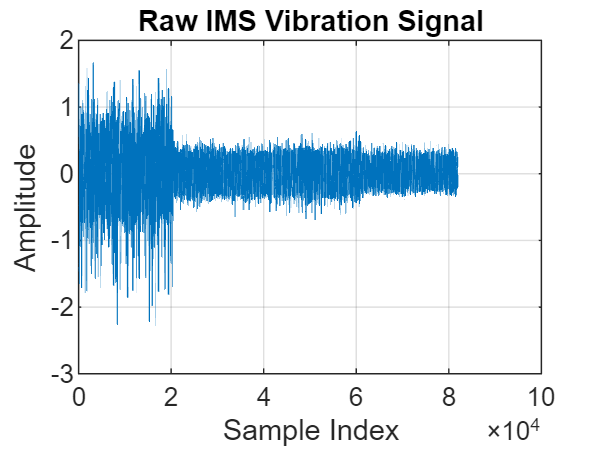


% Plot raw signal
figure;
plot(y);
title('Raw IMS Vibration Signal');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

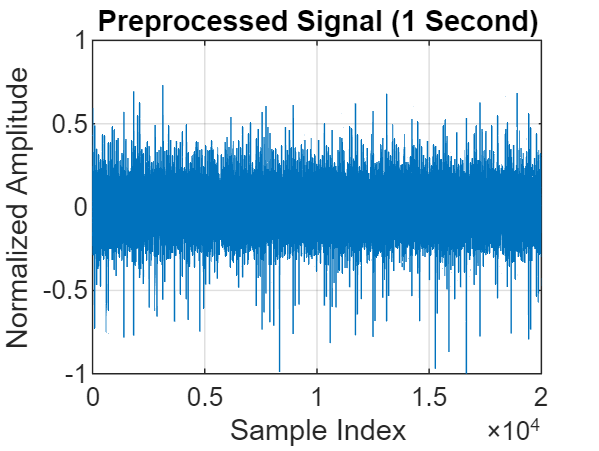


%% ============================================================
%  BLOCK 2: SIGNAL PREPROCESSING (1D)
%  ============================================================
%  Purpose:
%  - Remove DC offset
%  - Normalize amplitude
%  - Select manageable segment
%  ============================================================

T = 1;                           % 1 second segment
N = Fs * T;

y_seg = y(1:N);                  % Segment selection
y_seg = y_seg - mean(y_seg);     % Mean removal
y_seg = y_seg / max(abs(y_seg)); % Normalization

figure;
plot(y_seg);
title('Preprocessed Signal (1 Second)');
xlabel('Sample Index');
ylabel('Normalized Amplitude');
grid on;


%% ============================================================
%  BLOCK 3: MATRIX CONSTRUCTION
%  ============================================================
%  Overlap = l - 1 gives Hankel structure
%  ============================================================

l = 40;                  % Patch length
overlap = l - 1;         % Maximum overlap

Y = buffer(y_seg, l, overlap, 'nodelay');

fprintf('Constructed matrix size: %d x %d\n', size(Y,1), size(Y,2));

Constructed matrix size: 40 x 19961


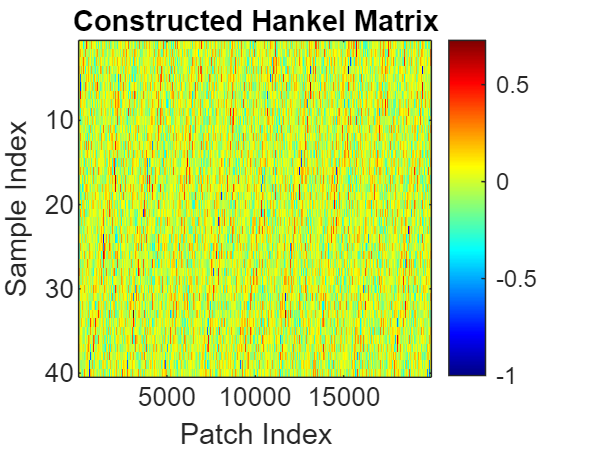


figure;
imagesc(Y);
colormap jet;
colorbar;
title('Constructed Hankel Matrix');
xlabel('Patch Index');
ylabel('Sample Index');


fprintf('\n--- Hankel Matrix Verification ---\n');


--- Hankel Matrix Verification ---


fprintf('First 5 elements of first column:\n');

First 5 elements of first column:


disp(Y(1:5,1));

   -0.2064
   -0.0941
   -0.0287
    0.0322
    0.1511




fprintf('First 5 elements of last column:\n');

First 5 elements of last column:


disp(Y(1:5,end));

    0.3196
    0.3033
    0.1770
    0.0248
   -0.1314




fprintf('Frobenius norm of Y: %.6f\n', norm(Y,'fro'));

Frobenius norm of Y: 127.649853



%% ============================================================
%  BLOCK 4: SVD DECOMPOSITION
%  ============================================================
%  Y = U * Sigma * V^T
%  ============================================================

[U, S, V] = svd(Y, 'econ');
sigma = diag(S);

fprintf('\n--- SVD Verification ---\n');


--- SVD Verification ---


fprintf('Top 10 singular values:\n');

Top 10 singular values:


disp(sigma(1:10));

   42.9187
   42.9131
   40.6069
   40.1348
   30.0575
   29.8101
   24.8204
   23.9069
   22.3362
   22.2927




energy_total = sum(sigma.^2);
energy_top10 = sum(sigma(1:10).^2);

fprintf('Energy retained by top 10 SVs: %.2f %%\n', ...
        100 * energy_top10 / energy_total);

Energy retained by top 10 SVs: 67.01 %


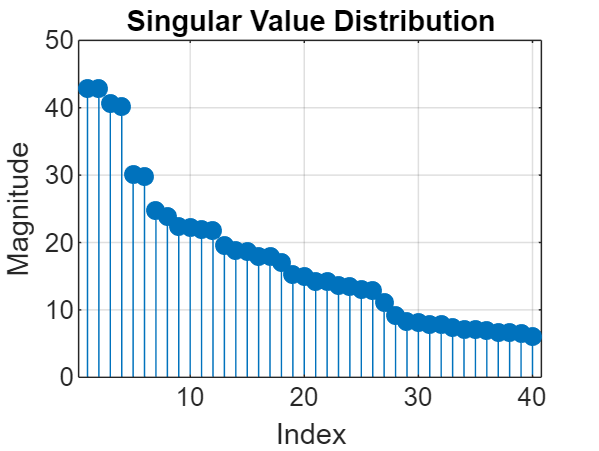


figure;
stem(sigma, 'filled');
title('Singular Value Distribution');
xlabel('Index');
ylabel('Magnitude');
grid on;


%% ============================================================
%  BLOCK 5: TSVD (TRUNCATED SVD)
%  ============================================================
%  TSVD = Hard thresholding of singular values
%  ============================================================

t = 10;   % Truncation index (can be tuned)

S_tsvd = S;
S_tsvd(t+1:end, t+1:end) = 0;

X_tsvd = U * S_tsvd * V';

%% ============================================================
%  BLOCK 6: RSVD
%  ============================================================
%  RSVD uses Periodic Modulation Intensity (PMI)
%  to identify fault-related components.
%  ============================================================

numSV = length(sigma);
PMI = zeros(numSV,1);

for i = 1:numSV
    
    % i-th right singular vector
    vi = V(:,i);
    
    % Envelope of vi
    env_vi = abs(hilbert(vi));
    env_vi = env_vi - mean(env_vi);
    
    % FFT of envelope
    L = length(env_vi);
    NFFT = 2^nextpow2(L);
    ENV_FFT = fft(env_vi, NFFT);
    
    mag = abs(ENV_FFT(1:NFFT/2+1));
    
    % PMI = Ratio of maximum spectral peak to average spectral energy
    PMI(i) = max(mag) / (mean(mag) + eps);
end

% Normalize PMI to [0,1]
PMI = PMI / max(PMI);

% RSVD singular value reweighting
sigma_rsvd = PMI .* sigma;

S_rsvd = diag(sigma_rsvd);

X_rsvd = U * S_rsvd * V';

%% ============================================================
%  BLOCK 7: WSSVD (WEIGHTED SOFT SVD) - PROPOSED METHOD
%  ============================================================
%  Uses weighted soft thresholding
%  ============================================================

lambda = 0.05;                     % Regularization parameter

w = 1 ./ (sigma / max(sigma) + eps);   % Weights

sigma_w = sign(sigma) .* max(abs(sigma) - lambda * w, 0);

S_wssvd = diag(sigma_w);

X_wssvd = U * S_wssvd * V';

fprintf('\n--- Singular Value Modification ---\n');


--- Singular Value Modification ---



fprintf('Original sigma (first 10):\n');

Original sigma (first 10):


disp(sigma(1:10));

   42.9187
   42.9131
   40.6069
   40.1348
   30.0575
   29.8101
   24.8204
   23.9069
   22.3362
   22.2927




fprintf('TSVD sigma (first 10):\n');

TSVD sigma (first 10):


disp(diag(S_tsvd(1:10,1:10)));

   42.9187
   42.9131
   40.6069
   40.1348
   30.0575
   29.8101
   24.8204
   23.9069
   22.3362
   22.2927




fprintf('RSVD sigma (first 10):\n');

RSVD sigma (first 10):


disp(diag(S_rsvd(1:10,1:10)));

   42.9187
   41.7896
   21.9376
   20.6471
   26.3057
   25.8814
    8.7275
    8.4330
   17.4777
   11.4631




fprintf('WSSVD sigma (first 10):\n');

WSSVD sigma (first 10):


disp(diag(S_wssvd(1:10,1:10)));

   42.8687
   42.8631
   40.5540
   40.0813
   29.9861
   29.7381
   24.7339
   23.8172
   22.2402
   22.1965




%% ============================================================
%  BLOCK 8: SIGNAL RECONSTRUCTION
%  ============================================================

x_tsvd  = reconstruct_signal(X_tsvd,  l, overlap);
x_rsvd  = reconstruct_signal(X_rsvd,  l, overlap);
x_wssvd = reconstruct_signal(X_wssvd, l, overlap);

%% QUANTITATIVE METRICS

err_tsvd  = norm(y_seg - x_tsvd(1:N)) / norm(y_seg);
err_rsvd  = norm(y_seg - x_rsvd(1:N)) / norm(y_seg);
err_wssvd = norm(y_seg - x_wssvd(1:N)) / norm(y_seg);

fprintf('\n--- Reconstruction Error (Relative) ---\n');


--- Reconstruction Error (Relative) ---


fprintf('TSVD  Error: %.4f\n', err_tsvd);

TSVD  Error: 0.5220


fprintf('RSVD  Error: %.4f\n', err_rsvd);

RSVD  Error: 0.4654


fprintf('WSSVD Error: %.4f\n', err_wssvd);

WSSVD Error: 0.0094


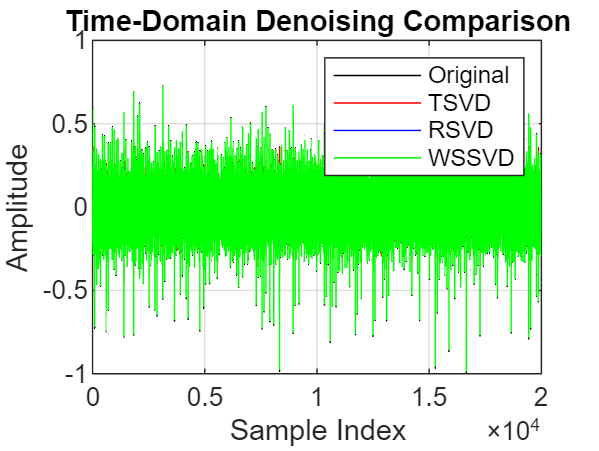


%% ============================================================
%  BLOCK 9: TIME-DOMAIN COMPARISON
%  ============================================================

figure;
plot(y_seg, 'k'); hold on;
plot(x_tsvd, 'r');
plot(x_rsvd, 'b');
plot(x_wssvd, 'g');
legend('Original','TSVD','RSVD','WSSVD');
title('Time-Domain Denoising Comparison');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;



%% ============================================================
%  FUNCTION: SIGNAL RECONSTRUCTION
%  ============================================================
function x_rec = reconstruct_signal(X, l, overlap)

    [~, n] = size(X);
    step = l - overlap;
    x_len = l + (n-1)*step;

    x_rec = zeros(x_len,1);
    weight = zeros(x_len,1);

    for k = 1:n
        idx = (k-1)*step + (1:l);
        x_rec(idx) = x_rec(idx) + X(:,k);
        weight(idx) = weight(idx) + 1;
    end

    x_rec = x_rec ./ weight;
end

%% ============================================================
%  MATRIX-LEVEL COMPARISON (BEFORE vs AFTER DENOISING)
%  ============================================================

fprintf('\n========== MATRIX COMPARISON ==========\n');


========== MATRIX COMPARISON ==========



% Dimensions
fprintf('Original Matrix Y size      : %d x %d\n', size(Y,1), size(Y,2));

Original Matrix Y size      : 40 x 19961


fprintf('WSSVD Matrix size           : %d x %d\n', size(X_wssvd,1), size(X_wssvd,2));

WSSVD Matrix size           : 40 x 19961



% Frobenius norms
norm_Y  = norm(Y, 'fro');
norm_Xw = norm(X_wssvd, 'fro');

fprintf('Frobenius norm of Y         : %.4f\n', norm_Y);

Frobenius norm of Y         : 127.6499


fprintf('Frobenius norm of WSSVD(Y)  : %.4f\n', norm_Xw);

Frobenius norm of WSSVD(Y)  : 126.9817



% Relative change
fprintf('Relative norm reduction    : %.2f %%\n', ...
        100*(norm_Y - norm_Xw)/norm_Y);

Relative norm reduction    : 0.52 %


%% ============================================================
%  FAULT FREQUENCY CALCULATION (IMS BEARING)
%  ============================================================

% Bearing parameters (IMS dataset - standard)
fr = 2000/60;      % Shaft speed in Hz
n  = 8;            % Number of rolling elements
d  = 7.92e-3;      % Ball diameter (m)
D  = 34.55e-3;     % Pitch diameter (m)
theta = 0;         % Contact angle (rad)

% Fault frequencies
BPFO = (n/2)*fr*(1 - (d/D)*cos(theta));
BPFI = (n/2)*fr*(1 + (d/D)*cos(theta));

fprintf('\n--- Fault Frequencies ---\n');


--- Fault Frequencies ---


fprintf('Shaft frequency (fr): %.2f Hz\n', fr);

Shaft frequency (fr): 33.33 Hz


fprintf('BPFO: %.2f Hz\n', BPFO);

BPFO: 102.77 Hz


fprintf('BPFI: %.2f Hz\n', BPFI);

BPFI: 163.90 Hz


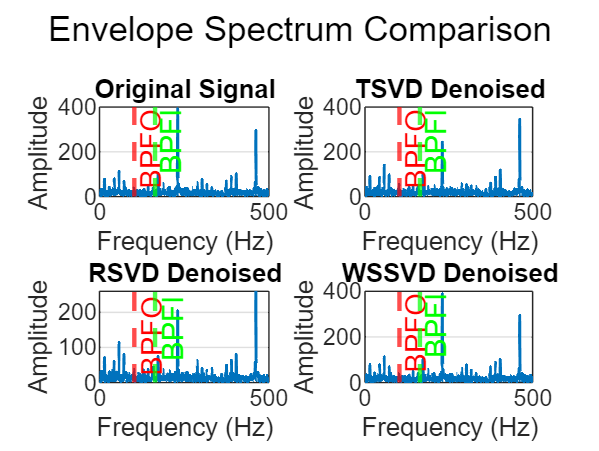

%% ============================================================
%  ENVELOPE SPECTRUM ANALYSIS
%    -> Envelope spectrum is used to reveal fault frequencies
%  ============================================================

signals = { ...
    y_seg, ...
    x_tsvd(1:N), ...
    x_rsvd(1:N), ...
    x_wssvd(1:N) ...
};

signal_names = { ...
    'Original Signal', ...
    'TSVD Denoised', ...
    'RSVD Denoised', ...
    'WSSVD Denoised' ...
};

figure;

for k = 1:length(signals)

    x = signals{k};

    % Step 1: Hilbert transform
    x_hilbert = hilbert(x);

    % Step 2: Envelope extraction
    envelope = abs(x_hilbert);

    % Step 3: Remove DC component
    envelope = envelope - mean(envelope);

    % Step 4: FFT of envelope
    L = length(envelope);
    NFFT = 2^nextpow2(L);
    ENV_FFT = fft(envelope, NFFT);

    f = Fs*(0:(NFFT/2))/NFFT;
    mag = abs(ENV_FFT(1:NFFT/2+1));

    % Step 5: Plot envelope spectrum
    subplot(2,2,k);
    plot(f, mag, 'LineWidth', 1);
    xlim([0 500]);   % Fault frequencies are low
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title(signal_names{k});
    grid on;

    hold on;
    xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
    xline(BPFI, '--g', 'BPFI', 'LineWidth', 1.5);
    hold off;

end

sgtitle('Envelope Spectrum Comparison');

%% ============================================================
%  RESONANCE BAND EXTRACTION
%  ============================================================

% Typical resonance band for IMS bearings
f_low  = 500;   % Hz
f_high = 5000;  % Hz

[b, a] = butter(4, [f_low f_high]/(Fs/2), 'bandpass');

% Apply to WSSVD signal
x_wssvd_bp = filtfilt(b, a, x_wssvd(1:N));

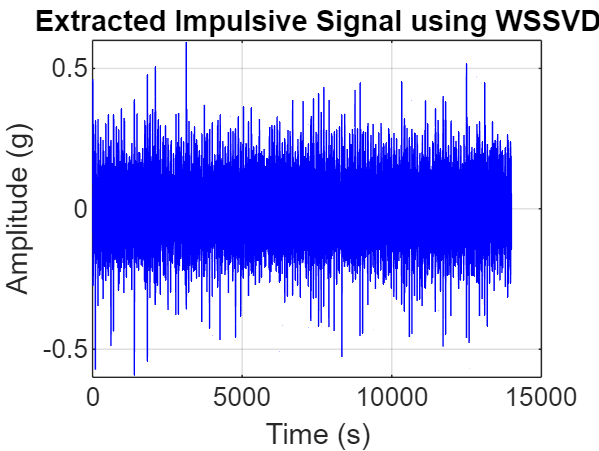

%% ============================================================
%  IMPULSIVE TIME SIGNAL 
%  ============================================================

T_plot = 0.7;                    % seconds
Ns = round(T_plot * Fs);

figure;
plot(x_wssvd_bp(1:Ns), 'b');
xlabel('Time (s)');
ylabel('Amplitude (g)');
title('Extracted Impulsive Signal using WSSVD');
grid on;

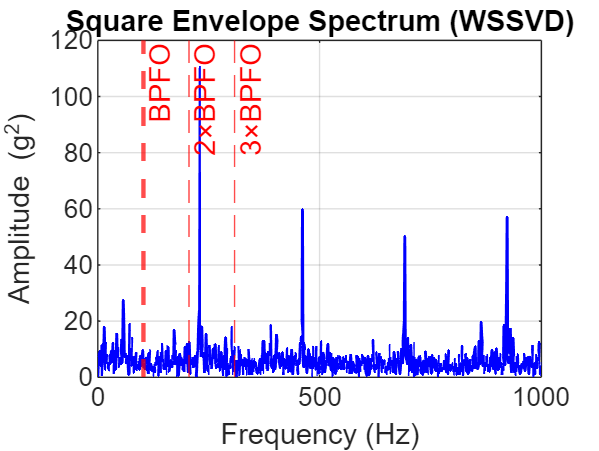

%% ============================================================
%  SQUARE ENVELOPE SPECTRUM 
%  ============================================================

x = x_wssvd_bp(1:Ns);

env = abs(hilbert(x));
env_sq = env.^2;
env_sq = env_sq - mean(env_sq);

L = length(env_sq);
NFFT = 2^nextpow2(L);
ENV_FFT = fft(env_sq, NFFT);

f = Fs*(0:(NFFT/2))/NFFT;
mag = abs(ENV_FFT(1:NFFT/2+1));

figure;
plot(f, mag, 'b', 'LineWidth', 1);
xlim([0 1000]);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g^2)');
title('Square Envelope Spectrum (WSSVD)');
grid on;

hold on;
xline(BPFO, '--r', 'BPFO', 'LineWidth', 1.5);
xline(2*BPFO, '--r', '2×BPFO');
xline(3*BPFO, '--r', '3×BPFO');
hold off;